## Experimenta data

clc; clear; close all; format shortEng; warning('off','all')

x  = readmatrix('datos.xlsx','Sheet','peso seco');
chl  = readmatrix('datos.xlsx','Sheet','clorofilas');
car = readmatrix('datos.xlsx','Sheet','carotenoides');
n  = readmatrix('datos.xlsx','Sheet','nitratos');
p  = readmatrix('datos.xlsx','Sheet','fosfatos');
u  = readmatrix('datos.xlsx','Sheet','urea');

to = x(1:10,1); 
to = to(:);
nrep = size(x,2)-1; 

## Nonlinear regression


$$$$\dot{x} = x\left(\frac{\mu_{\max} S_N S_P}{S_{N0} S_{P0}} + \frac{\mu_{\max} S_{NU} S_P}{S_{P0} S_{NU0}}\right) - \mu_d x$$



$$$$\dot{Chl} = \mu_{\max}\theta_{Chl} x \left(1 - \frac{Chl}{\phi_{Chl\max}}\right) - \frac{\theta_{Chl} r_P x}{S_P + \varepsilon_{SP}}$$
$$



$$$$\dot{Car} = \mu_{\max}\theta_{Car} x \left(1 - \frac{Car}{\phi_{Car\max}}\right) - \frac{\theta_{Car} r_P x}{S_P + \varepsilon_{SP}}$$
$$



$$$$\dot{S} = -\frac{\mu_{\max}\theta_T x S}{S_{0}}$$
$$



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>
    ParamNames      Var2         SE         MoE                CI95              pValue  
    __________    ________    ________    ________    ______________________    _________

    {'rho1' }      0.13341    0.024345    0.049652     0.083758      0.18306    5.423e-06
    {'rho5' }  

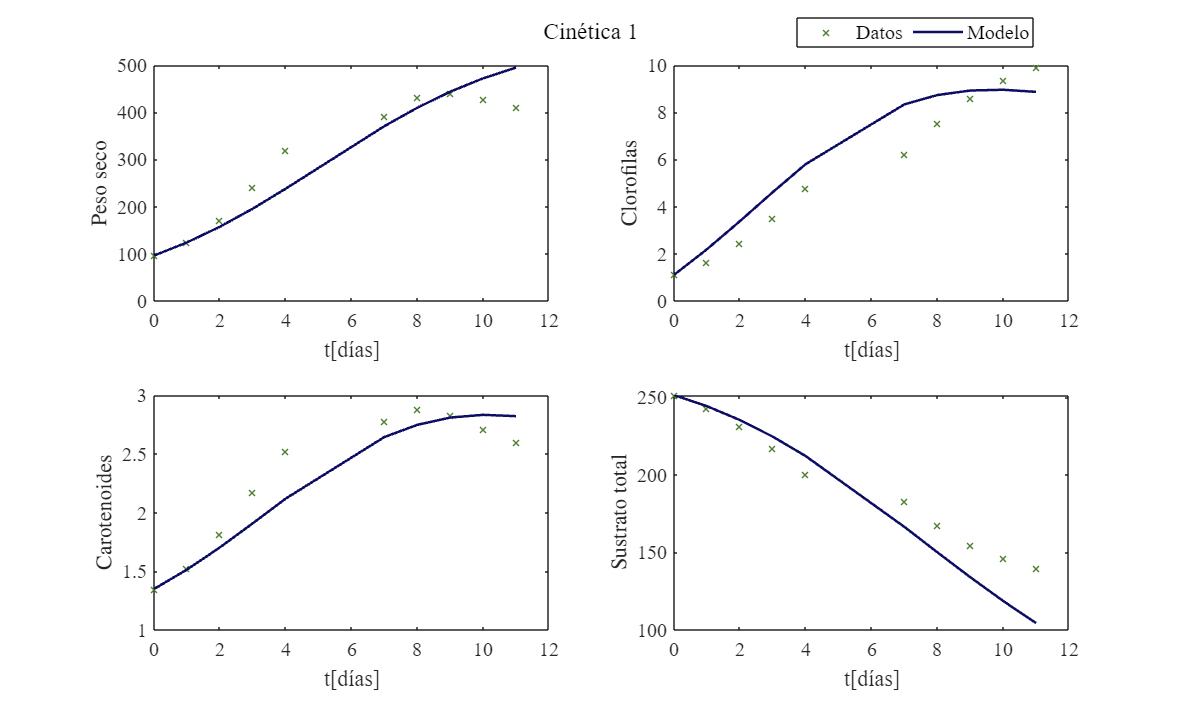


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>
    ParamNames     Var2         SE         MoE                CI95               pValue 
    __________    _______    ________    _______    ________________________    ________

    {'rho1' }     0.13341    0.066814    0.13627    -0.0028581       0.26968    0.

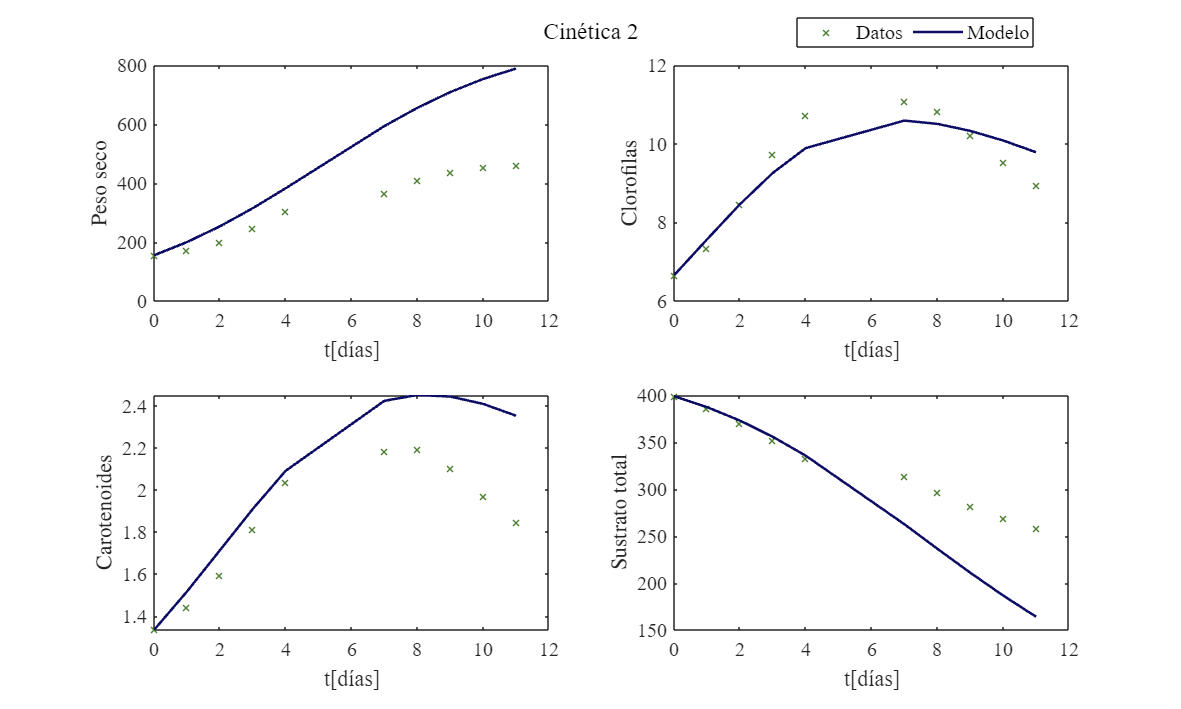


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>
    ParamNames      Var2         SE         MoE              CI95            pValue 
    __________    ________    ________    _______    ____________________    _______

    {'rho1' }      0.13341    0.053786     0.1097    0.023713     0.24311    0.01876
    {'rho5' }       0.0055    

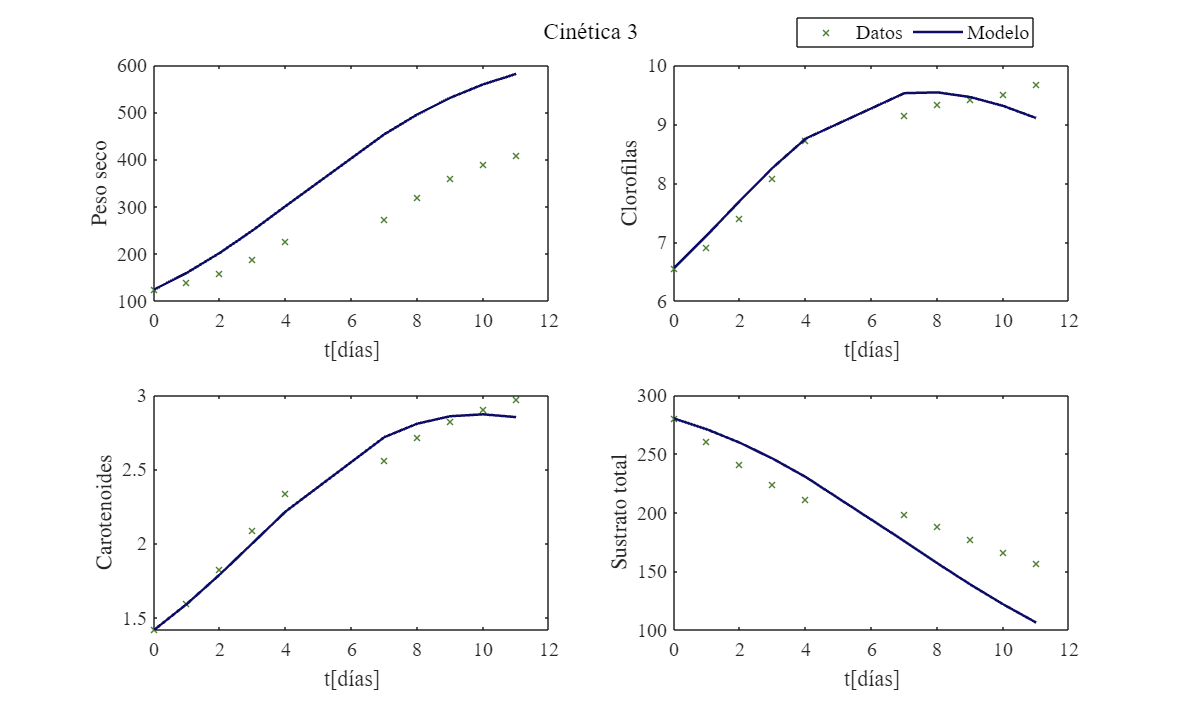

for j = 1:nrep

    uo = x(1:10,j+1);
    vo = chl(:,j);  
    wo = car(1:10,j+1);
    xo = n(1:10,j+1);
    yo = p(1:10,j+1);
    zo = u(1:10,j+1);

    %% Suavizado
    us = smoothdata(uo,"gaussian",9);
    vs = smoothdata(vo,"gaussian",9);
    ws = smoothdata(wo,"gaussian",9);
    xs = smoothdata(xo,"gaussian",9);
    ys = smoothdata(yo,"gaussian",9);
    zs = smoothdata(zo,"gaussian",9);
    

    Ss = xs + ys + zs;

   
    [Estimate,SE,MoE,CI95,pValue,fa,mdl,ua,va,wa,Sa] = fitting_model(to,us,vs,ws,xs,ys,zs);
    plot_Results(to,us,vs,ws,Ss,to,ua,va,wa,Sa,['Cinética ',num2str(j)]);

end

## Functions

### Function: Nonlinear regression algorithm

function [Estimate,SE,MoE,CI95,pValue,fa,mdl,ua,va,wa,Sa] = fitting_model(to,usuave,vsuave,wsuave,xsuave,ysuave,zsuave)
  
    to = to(:);
    usuave = usuave(:);
    vsuave = vsuave(:);
    wsuave = wsuave(:);
    xsuave = xsuave(:);
    ysuave = ysuave(:);
    zsuave = zsuave(:);

   
    u0 = usuave(1); v0 = vsuave(1); w0 = wsuave(1);
    x0 = xsuave(1); y0 = ysuave(1); z0 = zsuave(1);

    S0 = x0 + y0 +z0;

    %% PARÁMETROS 
    rho1 = 0.14724;

    rho2 = x0;
    rho3 = y0;
    rho4 = z0;

    rho5 = 0.005;
    rho6 = 0.11;
    rho7 = 12.5;

    rho8 = 0.075802;
    rho9 = 0.021517;
    rho10 = 3.4;
    rho11 = 0.077;

    rho12 = 0.147637044;
    rho13 = 0.017861744;
    rho14 = 0.261044144;

    rho15 = rho8/rho1;

    rho16 = rho12 + rho13 + rho14;
    rho18 = rho2 + rho3 + rho4;

    P = [rho1,rho5,rho6,rho7,rho8,rho9,rho10,rho11,rho16];

    Ss = xsuave + ysuave + zsuave;
    fo = [usuave;vsuave;wsuave;Ss];
    to_fit = [to;to;to;to];

    %% Límites 
    low = [0.13341;0.0045;0.10;11.25;0.068;0.019;3.1;0.070;0.40];

    sup = [0.15649;0.0055;0.121;13.75;0.082;0.023;3.7;0.084;0.50];


    opts = optimoptions('lsqcurvefit',...
        'MaxFunctionEvaluations',300000,...
        'MaxIterations',1E4,...
        'FunctionTolerance',1E-8);

    [Estimate,~,residual,~,~,~,J] = lsqcurvefit(@modelo,P,to_fit,fo,low,sup,opts);

    fa = modelo(Estimate,to_fit);

    
    dof = numel(fo) - length(P);
    covv = inv(J'*J)*(residual'*residual/dof);
    SE = sqrt(diag(covv));

    tval = tinv(0.975,dof);
    MoE = SE * tval;

    CI95 = [Estimate'-MoE, Estimate'+MoE];

    t_stat = Estimate'./SE;
    pValue = 2*(1 - tcdf(abs(t_stat),dof));

    mdl = table(Estimate',SE,MoE,pValue);

  
    fa_r = reshape(fa,[],4);

    ua = fa_r(:,1);
    va = fa_r(:,2);
    wa = fa_r(:,3);
    Sa = fa_r(:,4);

    
    ParamNames = {'rho1';'rho5';'rho6';'rho7';'rho8';'rho9';'rho10';'rho11';'rho16'};
    Results = table(ParamNames,Estimate',SE,MoE,CI95,pValue);
    disp(Results)

    function fa = modelo(P,t)

        t = reshape(t,[],4); t = t(:,1);

        rho1=P(1); rho5=P(2); rho6=P(3); rho7=P(4);
        rho8=P(5); rho9=P(6); rho10=P(7); rho11=P(8);
        rho16=P(9);
        

        dt = 1E-2;
        time = (0:dt:max(t))';
        n = length(time)-1;

        u=zeros(n+1,1); v=u; w=u; S = u;
        u(1) = u0;
        v(1) = v0;
        w(1) = w0;
        S(1) = S0;

        for i=1:n
            [du,dv,dw,dS]=f(u(i),v(i),w(i),S(i));

            un = u(i) + du*dt;
            vn = v(i) + dv*dt;
            wn = w(i) + dw*dt;
            Sn = S(i) + dS*dt;

            [dun,dvn,dwn,dSn] = f(un,vn,wn,Sn);

            u(i+1) = u(i) + (du+dun)*dt/2;
            v(i+1) = v(i) + (dv+dvn)*dt/2;
            w(i+1) = w(i) + (dw+dwn)*dt/2;
            S(i+1) = S(i) + (dS+dSn)*dt/2;
        end

        
        uk=zeros(length(t),1);
        vk=zeros(length(t),1);
        wk=zeros(length(t),1);
        Sk=zeros(length(t),1);
        

        for i=1:length(t)
            k=abs(time-t(i))<1E-9;

            uk(i)=u(k);
            vk(i)=v(k);
            wk(i)=w(k);
            Sk(i)=S(k);
            
        end

        fa=[uk;vk;wk;Sk];

        function [du,dv,dw,dS]=f(u,v,w,S)
            x = (rho2/rho18)*S;
            y = (rho3/rho18)*S;
            z = (rho4/rho18)*S;

            du = (u*((rho1*x/rho2)*(y/rho3)+(rho1*z/rho4)*(y/rho3)))-(rho5*u);
            dv = (rho1*rho6*u*(1-(v/rho7)))-(rho6*rho8*u/(y+rho15));
            dw = (rho1*rho9*u*(1-(w/rho10)))-(rho9*rho11*u/(y+rho15));
            dS = -(rho1*rho16*u*S)/rho18;
        end
    end
end

### Plot:

function plot_Results(to,ue,ve,we,Se,time,ua,va,wa,Sa,titulo)

    set(figure(),'Color','w');

    set(gcf,'Units','Centimeters','Position',[2 2 25 15]);

    FS = 12;

    v_exp = {ue,ve,we,Se};

    v_mod = {ua,va,wa,Sa};

    labels = {'Peso seco','Clorofilas','Carotenoides','Sustrato total'};

    for i = 1:4

        subplot(2,2,i);

        hold on;
        box on;

        plot(to,v_exp{i},'x','LineWidth',1,'MarkerSize',5,'Color',[0.3 0.5 0.2]);

        plot(time,v_mod{i},'-','LineWidth',1.5,'Color',[0.05 0.05 0.4]);

        xlabel('t[días]','Interpreter','latex','FontSize',FS);

        ylabel(labels{i},'Interpreter','latex','FontSize',FS);

        set(gca,'FontName','Times New Roman','FontSize',FS);

    end

    lgd = legend({'Datos', 'Modelo'}, 'FontName', 'Times New Roman', 'FontSize', FS);
    lgd.Orientation = 'horizontal';
    lgd.Position = [0.70, 0.94, 0.15, 0.03]; 

    sgtitle(titulo,'Interpreter', 'latex', 'FontSize', FS + 2, 'FontName', 'Times New Roman');


end